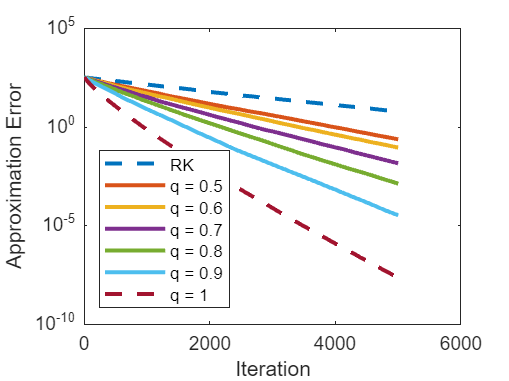

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% Add path to functions
addpath('Functions\')

% Store path to custom matrices
filepath = "Matrix\";

%   Algorithm parameters
MAX_ITERATIONS  = 5000;

% q0:       Lowest quantile used
% steps:    How many quantiles between q0 and 1 to useS
q0              = 1/2;
steps           = 5;

% Matrix Setup
mat_type            = "gaussian";
mat_name            = "ash958";
extension           = ".mat";
[m,n,A,x,b]         = SystemSetup(5000,1000,mat_type,0,filepath+mat_name+extension);

% Graph Parameters 
% xpoints and graphstep serve to only display every graphstep-th point of the graph
graphstep       = 100;
xpoints         = 1:graphstep:MAX_ITERATIONS+1;

%------------------------------------------------------

% Initialization 
xk      = zeros(n,1);
mxk     = zeros(n,1);
lqxk    = zeros(n,1);

% Data collection values
err     = zeros(MAX_ITERATIONS+1, 1);
merr    = zeros(MAX_ITERATIONS+1, 1);
lqerr   = zeros(MAX_ITERATIONS+1, 1);

err(1)      = norm(x - xk)^2;
merr(1)     = norm(x - xk)^2;
lqerr(1)     = norm(x - xk)^2;

% RK and rqRK with quantile (m-1)/m
for iter = 1:MAX_ITERATIONS
    % RK
    xk  = RKalgstep(A,xk,b);

    % MaxRK
    N1tmp   = b - A * mxk;
    N1      = abs(N1tmp);
    [~,i]   = max(N1);

    % x_k+1 = x_k + (b_i - <a_i,x_k>) a_i
    mxk = mxk + A(i,1:n)' * N1tmp(i);

    %   Data collection
    err(iter + 1)       = norm(x - xk)^2;
    merr(iter + 1)      = norm(x - mxk)^2; 
end

% Run rqRK with varying quantiles and plot error graphs 
errgraph = semilogy(xpoints, err(xpoints),'--','DisplayName','RK','LineWidth',2);
hold on

% Run rqRK for each q
for qstep = 1:steps
    q = q0 + (qstep - 1) / steps * (1 - q0); 

    % Initialize for rqRK
    lqxk        = zeros(n,1);
    
    lqerr(1)    = norm(x - lqxk)^2;

    for iter = 1:MAX_ITERATIONS
        lqxk = rqRKalgstep(A,lqxk,b,q);
    
        %   Data collection
        lqerr(iter + 1)     = norm(x - lqxk)^2;
    end 

    semilogy(xpoints, lqerr(xpoints),'DisplayName',"q = " + q,'LineWidth',2);
end 

q = (m-1)/m;
semilogy(xpoints, merr(xpoints),'--','DisplayName',"q = " + q, 'LineWidth',2);

legend('Location','southwest')
xlabel("Iteration")
ylabel("Approximation Error")
hold off

% Save tikz plot
if mat_type ~= "custom"
    mat_name = mat_type;
end
filename = "Figs\rqRK_" + mat_name;
saveas(errgraph, filename, 'fig');
filename = convertStringsToChars(filename+".tex");
matlab2tikz(filename)